% Clear workspace
clear,clc, close all
% Images Datapath – You can modify your path accordingly 
datapath='CT3';
 
% Image Datastore
imds=imageDatastore(datapath, ...  
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); %Datastore for image data


All_samples=countEachLabel(imds) %Count files in ImageDatastore labels

All_samples = 2×2 table
      Label      Count
    _________    _____

    COVID        1252 
    non-COVID    1229 


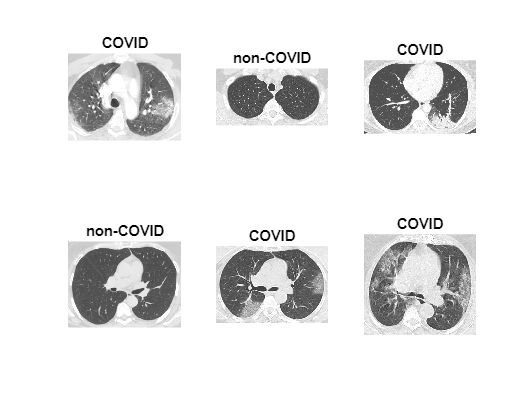


% Number of Images
num_images=length(imds.Labels);

% Visualize random images
randper=randperm(num_images,6); %Random permutation of integers
figure;
for idx=1:length(randper)
    
    subplot(2,3,idx); %Create axes in tiled positions
    imshow(imread(imds.Files{randper(idx)}));
    title((imds.Labels(randper(idx))))
    
end



% Split the Training and Testing Dataset
[imdsTrain,imdsTest] = splitEachLabel(imds,.8,'randomized'); %Split ImageDatastore labels 
% Split the Training and Validation
valid_percent=0.1;
%[imdsValid,imdsTrain]=splitEachLabel(imdsTrain,valid_percent,'randomize');

train_split=countEachLabel(imdsTrain);

%[imdsTrain,imdsTest] = splitEachLabel(imds,.8,'randomized'); %Split ImageDatastore labels by proportions


net=resnet50;
    lgraph = layerGraph(net) % Extract all layers

lgraph =   LayerGraph with properties:

     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}
         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]


        lgraph.Layers % visualize all layers

ans =   177×1 Layer array with layers:

     1   'input_1'                      Image Input                  224×224×3 images with 'zerocenter' normalization
     2   'conv1'                        2-D Convolution              64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'bn_conv1'                     Batch Normalization          Batch normalization with 64 channels
     4   'activation_1_relu'            ReLU                         ReLU
     5   'max_pooling2d_1'              2-D Max Pooling              3×3 max pooling with stride [2  2] and padding [1  1  1  1]
     6   'res2a_branch2a'               2-D Convolution              64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'bn2a_branch2a'                Batch Normalization          Batch normalization with 64 channels
     8   'activation_2_relu'            ReLU                         ReLU
     

    lgraph.Layers(175).OutputSize % get number of classes in resnet-50

ans = 1000

    clear net;

    numClasses = numel(categories(imdsTrain.Labels)) %Number of array elements

numClasses = 2

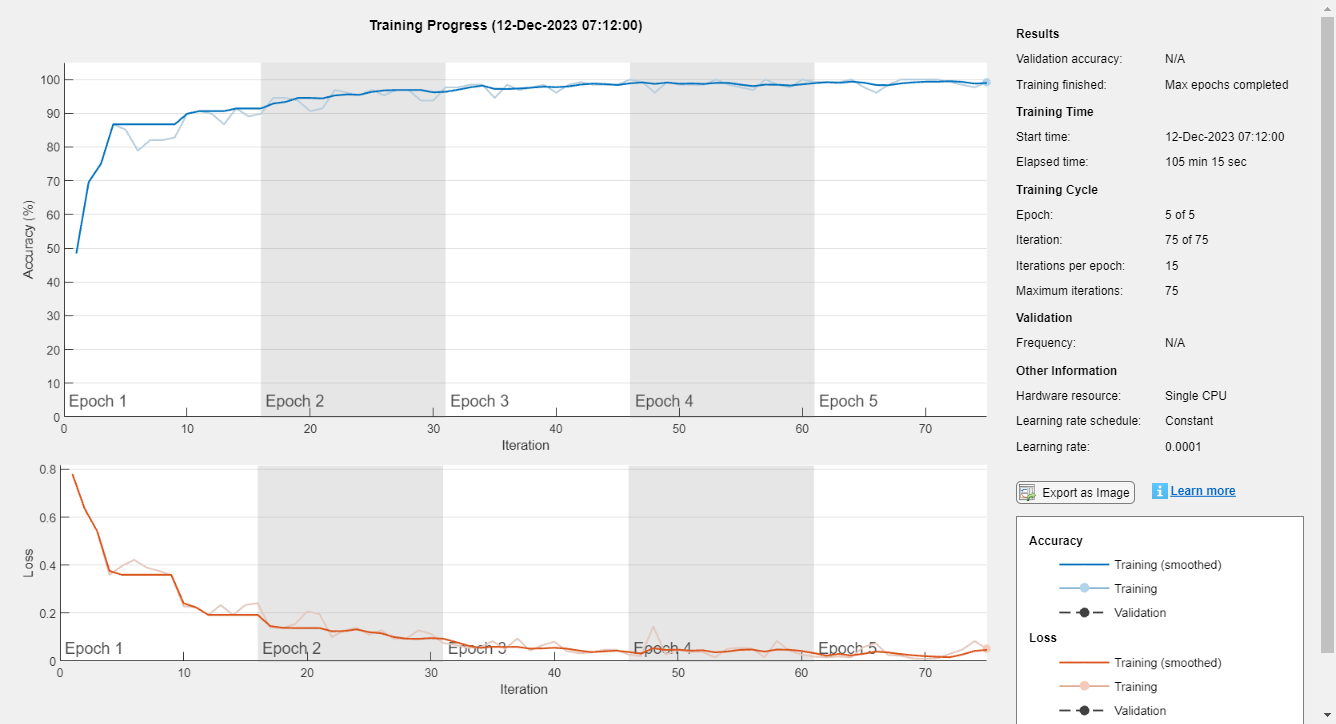


    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);


      lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);
    %A softmax layer applies a softmax function to the input.
    newsoftmaxLayer = softmaxLayer('Name','new_softmax');
    lgraph = replaceLayer(lgraph,'fc1000_softmax',newsoftmaxLayer);
    %A classification layer computes the cross entropy loss for multi-class
   %  classification problems with mutually exclusive classes.
    newClassLayer = classificationLayer('Name','new_classoutput');
    lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer);


    imdsTrain.ReadFcn = @(filename)preprocess_images(filename);
    imdsTest.ReadFcn = @(filename)preprocess_images(filename);

%[predicted_labels,posterior]=classify(netTransfer,imdsTest);

analyzeNetwork(lgraph)


    options = trainingOptions('adam',...
        'MaxEpochs',5,'MiniBatchSize',128,...
        'Shuffle','every-epoch', ...
        'InitialLearnRate',1e-4, ...   
        'Verbose',false, ...
        'Plots','training-progress'); %Options for training deep learning neural network



    augmenter = imageDataAugmenter( ...
        'RandRotation',[-5 5],'RandXReflection',1,...
        'RandYReflection',1,'RandXShear',[-0.05 0.05],'RandYShear',[-0.05 0.05]);


     auimds = augmentedImageDatastore([224 224],imdsTrain,'DataAugmentation',augmenter); 


     netTransfer = trainNetwork(auimds,lgraph,options);




      augtestimds = augmentedImageDatastore([224 224],imdsTest);
[predicted_labels,posterior] = classify(netTransfer,augtestimds);



sum(predicted_labels==imdsTest.Labels)/numel(predicted_labels)*100

ans = 96.9758

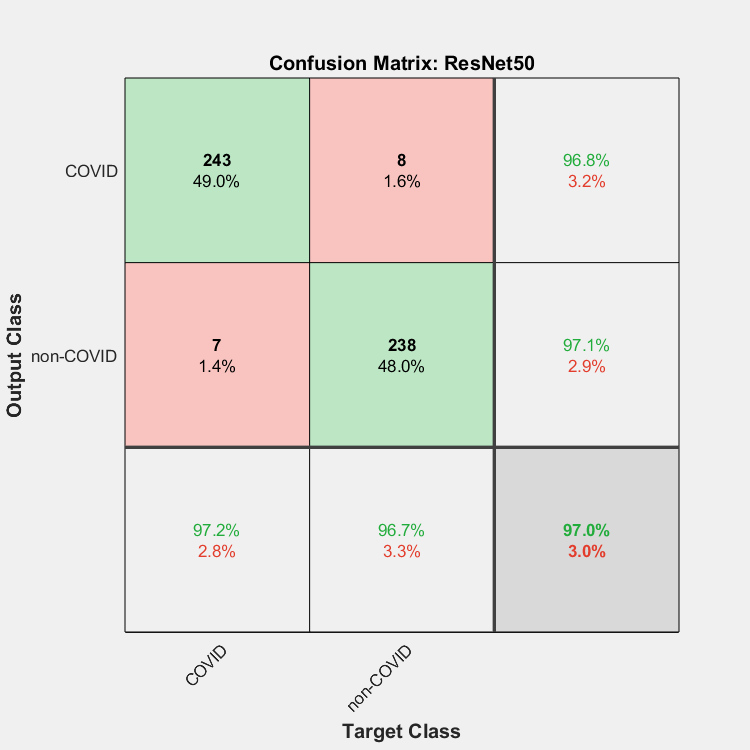




   % Actual Labels
actual_labels=imdsTest.Labels;

% Confusion Matrix
figure;
plotconfusion(actual_labels,predicted_labels)
title('Confusion Matrix: ResNet50');

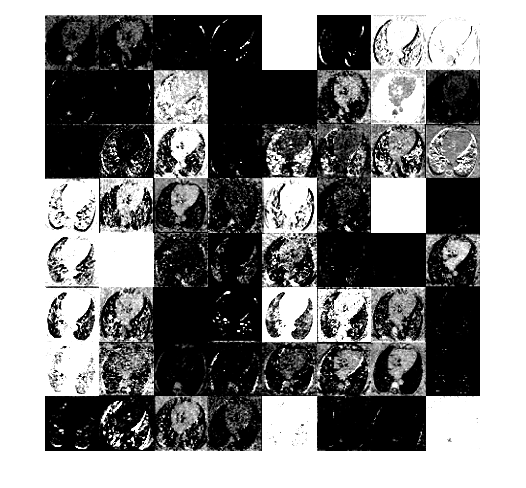


IMout = preprocess_images(imdsTest.Files{5});

    imResized = imresize(IMout,[[224 224]]);
    imageActivations = activations(netTransfer,imResized,'activation_2_relu');
   figure
    montage(imageActivations)

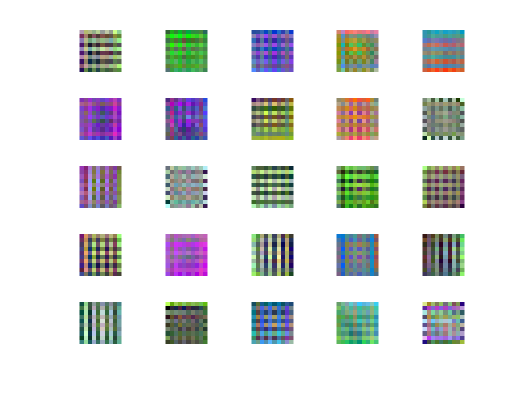


       layer = 'bn_conv1';
channels = 1:25;

I = deepDreamImage(netTransfer,layer,channels, ...
    'PyramidLevels',1, ...
    'Verbose',0);

figure
for i = 1:25
    subplot(5,5,i)
    imshow(I(:,:,:,i))
end

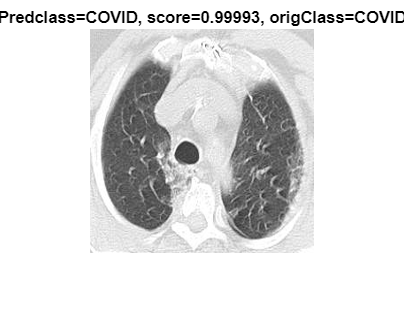



im = preprocess_images(imdsTest.Files{15});

    imResized = imresize(im,[224 224]);
    [ class, score]=classify(netTransfer,imResized);
    figure
    imshow(imResized)
    title([ 'Predclass=' char(string(class)),', ','score=',num2str(max(score)),', ','origClass=', char(string(imdsTest.Labels(1)))])

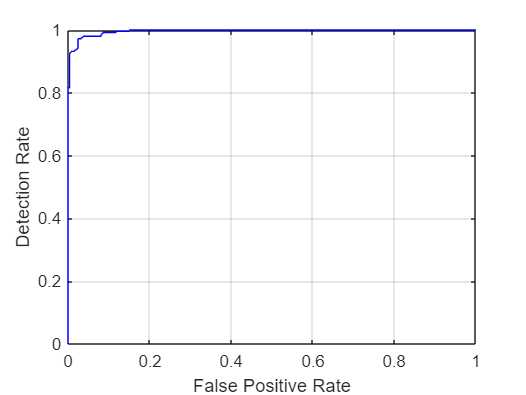



    %test_labels=imdsTest.Labels;
    classNames = netTransfer.Layers(end).Classes;

  

% ROC Curve - Our target class is the first class in this scenario 
%[fp_rate,tp_rate,T,AUC]=perfcurve(test_labels,posterior(:,1),1);
% actual_labels,predicted_labels



resp = (1:100)'>50;


test_labels=double(nominal(imdsTest.Labels));

% ROC Curve - Our target class is the first class in this scenario.
[fp_rate,tp_rate,T,AUC]=perfcurve(test_labels,posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');


% Area under the ROC value
AUC

AUC = single
0.9962


cm = confusionmat(actual_labels, predicted_labels);
cmt = cm'

cmt =    243     8
     7   238



diagonal = diag(cmt)

diagonal =    243
   238


sum_of_rows = sum(cmt, 2)

sum_of_rows =    251
   245



precision = diagonal ./ sum_of_rows

precision =     0.9681
    0.9714


overall_precision = mean(precision)

overall_precision = 0.9698


sum_of_columns = sum(cmt, 1)

sum_of_columns =    250   246



recall = diagonal ./ sum_of_columns'

recall =     0.9720
    0.9675


overall_recall = mean(recall)

overall_recall = 0.9697


f1_score = 2*((overall_precision*overall_recall)/(overall_precision+overall_recall))

f1_score = 0.9698

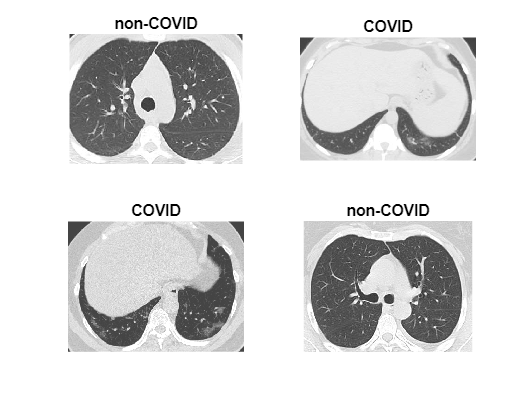




numTrainImages = numel(imds.Labels);
idx = randperm(numTrainImages,4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imds,idx(i));
    imshow(I), title(imds.Labels(idx(i)))
end



[YPred,scores] = classify(netTransfer,imdsTest);

Error using DAGNetwork/classify
Incorrect input size. The input images must have a size of [224 224 3].

YValidation = imdsTest.Labels;


idx = randperm(numel(imdsTest.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdstra,idx(i));
    imshow(I)
    label = YPred(idx(i));
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');
    else
        title(string(label), 'Color','red');
    end
end


%Grad-CAM

figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsTest,idx(i));
    I_resized = imresize(I,netTransfer.Layers(1).InputSize(1:2));
    label = YPred(idx(i));
    % scoreMap = gradCAM(netTransfer,I_resized,label);
    scoreMap = gradCAM(netTransfer,I_resized,label);
    alpha = 0.5;
    % plotGradCAM(I_resized,scoreMap,alpha);
    % imshow(I_resized)
    imshow(I_resized)
    hold on
    imagesc(scoreMap,'AlphaData',0.5)
    colormap jet
    colorbar
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');
    else
        title(string(label), 'Color','red');
    end
    hold off
end


%LIME

figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsTrain,idx(i));
    I_resized = imresize(I,netTransfer.Layers(1).InputSize(1:2));
    label = YPred(idx(i));
    scoreMap = imageLIME(netTransfer,I_resized,label);
    imshow(I_resized)
    hold on
    imagesc(scoreMap,'AlphaData',0.5)
    colormap jet
    colorbar
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');
    else
        title(string(label), 'Color','red');
    end
    hold off
end






    function IMout = preprocess_images(filename)

I = imread(filename);

if ~ismatrix(I) % if matrix is not in form m*n
    I=rgb2gray(I); 
end
IMout = cat(3,I,I,I); % creating matrix in the form of m*n*3
    end

  
